%Here we are going to implement the bisection method to solve the equation
%sin(x) = log(x) and we will plot the results


f = @(x) (sin(x) - log(x)); % function handle
x = bisection(f, 1, 3, 1e-4); % bisection solution

ya = 0.8415

yb = -0.9575

err = 1

y = 0.2162

a = 2

err = 0.5000

y = -0.3178

b = 2.5000

err = 0.2500

y = -0.0329

b = 2.2500

err = 0.1250

y = 0.0965

a = 2.1250

err = 0.0625

y = 0.0330

a = 2.1875

err = 0.0312

y = 3.7657e-04

a = 2.2188

err = 0.0156

y = -0.0162

b = 2.2344

err = 0.0078

y = -0.0079

b = 2.2266

err = 0.0039

y = -0.0037

b = 2.2227

err = 0.0020

y = -0.0017

b = 2.2207

err = 9.7656e-04

y = -6.5327e-04

b = 2.2197

err = 4.8828e-04

y = -1.3828e-04

b = 2.2192

err = 2.4414e-04

y = 1.1916e-04

a = 2.2190

err = 1.2207e-04

y = -9.5557e-06

b = 2.2191

err = 6.1035e-05

x = 2.2191

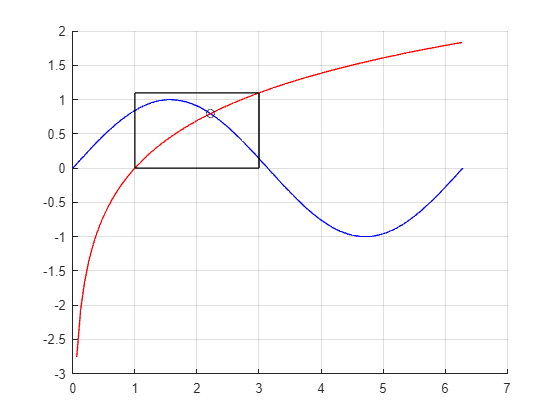

t = linspace(0, 2*pi); % uniform sampling
hold on
plot(t, sin(t), 'b') % sine curve
plot(t, log(t), 'r') % log curve
plot(x, sin(x), 'ko') % intersection
rectangle('Position', [1, 0, 2, log(3)]) % area of interest
grid on





% BISECTION method to solve f(x) = 0 for x
%
% Parameters:
% f function handle
% a, b endpoints of interval
% (assuming b > a and f(a)*f(b) < 0
% eps error tolerance
% Returns:
% x solution for f(x) = 0
%

function x = bisection(f, a, b, eps)
    ya = f(a)
    yb = f(b)
    err = (b - a) / 2
    while err > eps
        x = (a + b) / 2;
        y = f(x)
        if y * ya > 0
            a = x
        elseif y * yb > 0
            b = x
        else
            break;
        end
        err = err / 2
    end
    x = (a + b) / 2
end
